# Tugas Akhir Adsorbsi

------------------------------------------------------------------------------------------------------

Channel ID: **2328684**

Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik ( Percobaan Awal)

[data_1,timestamps_1,channelInfo] = thingSpeakRead(2328684,Fields=1,ReadKey='0FU0HYKO14RY4VAM',...
    DateRange=[datetime(2023,11,30,15,45,14),datetime(2023,11,30,19,43,50)])

data_1 =   184.8105
  188.5691
  189.0421
  191.8948
  182.9480
  187.1544
  189.5157
  184.8105
  191.8948
  190.9411


timestamps_1 = 849×1 datetime array
   30-Nov-2023 15:45:14
   30-Nov-2023 15:45:30
   30-Nov-2023 15:45:47
   30-Nov-2023 15:46:03
   30-Nov-2023 15:46:19
   30-Nov-2023 15:46:35
   30-Nov-2023 15:46:51
   30-Nov-2023 15:47:08
   30-Nov-2023 15:47:24
   30-Nov-2023 15:47:40
   30-Nov-2023 15:47:56
   30-Nov-2023 15:48:12
   30-Nov-2023 15:48:29
   30-Nov-2023 15:48:45
   30-Nov-2023 15:49:01
   30-Nov-2023 15:49:17
   30-Nov-2023 15:49:33
   30-Nov-2023 15:49:50
   30-Nov-2023 15:50:06
   30-Nov-2023 15:50:22
   30-Nov-2023 15:50:38
   30-Nov-2023 15:50:55
   30-Nov-2023 15:51:11
   30-Nov-2023 15:51:27
   30-Nov-2023 15:51:43
   30-Nov-2023 15:52:00
   30-Nov-2023 15:52:16
   30-Nov-2023 15:52:32
   30-Nov-2023 15:52:49
   30-Nov-2023 15:53:05


channelInfo = struct with fields:
            ChannelID: 2328684
                 Name: 'Tugas Akhir Adsorbsi'
          Description: 'Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik'
             Latitude: 0
            Longitude: 0
             Altitude: []
              Created: 02-Nov-2023 13:39:14
              Updated: 31-Jan-2024 08:35:15
          LastEntryID: 2718
    FieldDescriptions: {'Turbidity_1'  'Turbidity_2'  'Turbidity_3'  'Turbidity_4'}
             FieldIDs: [1 2 3 4]
                  URL: 'https://api.thingspeak.com/channels/2328684/field/1.json?'



% Plot Data
figure(1)
timestamps_1

timestamps_1 = 849×1 datetime array
   30-Nov-2023 15:45:14
   30-Nov-2023 15:45:30
   30-Nov-2023 15:45:47
   30-Nov-2023 15:46:03
   30-Nov-2023 15:46:19
   30-Nov-2023 15:46:35
   30-Nov-2023 15:46:51
   30-Nov-2023 15:47:08
   30-Nov-2023 15:47:24
   30-Nov-2023 15:47:40
   30-Nov-2023 15:47:56
   30-Nov-2023 15:48:12
   30-Nov-2023 15:48:29
   30-Nov-2023 15:48:45
   30-Nov-2023 15:49:01
   30-Nov-2023 15:49:17
   30-Nov-2023 15:49:33
   30-Nov-2023 15:49:50
   30-Nov-2023 15:50:06
   30-Nov-2023 15:50:22
   30-Nov-2023 15:50:38
   30-Nov-2023 15:50:55
   30-Nov-2023 15:51:11
   30-Nov-2023 15:51:27
   30-Nov-2023 15:51:43
   30-Nov-2023 15:52:00
   30-Nov-2023 15:52:16
   30-Nov-2023 15:52:32
   30-Nov-2023 15:52:49
   30-Nov-2023 15:53:05


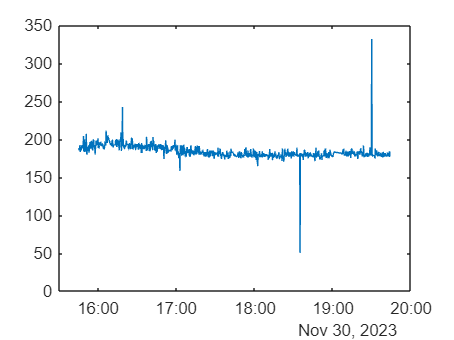

plot(timestamps_1,data_1)


% Remove outlier using mean
A = timetable(timestamps_1,data_1);
data_new = filloutliers(A,'nearest','mean');
for i = 1:height(data_new)
    data_new.Pump(i) = 100;
    data_new.Jumlah_adsorben(i)= 2;
end
data_new

data_new = 849×3 timetable
        timestamps_1        data_1    Pump    Jumlah_adsorben
    ____________________    ______    ____    _______________

    30-Nov-2023 15:45:14    184.81    100            2       
    30-Nov-2023 15:45:30    188.57    100            2       
    30-Nov-2023 15:45:47    189.04    100            2       
    30-Nov-2023 15:46:03    191.89    100            2       
    30-Nov-2023 15:46:19    182.95    100            2       
    30-Nov-2023 15:46:35    187.15    100            2       
    30-Nov-2023 15:46:51    189.52    100            2       
    30-Nov-2023 15:47:08    184.81    100            2       
    30-Nov-2023 15:47:24    191.89    100            2       
 

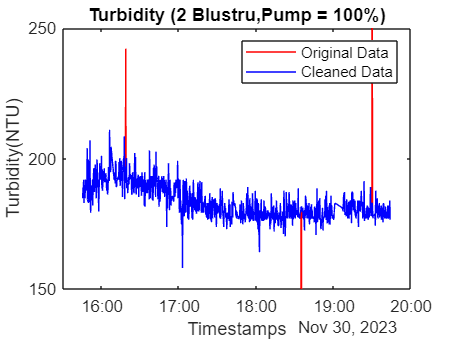


% visualize new_data
figure(2)
plot(timestamps_1,data_1,"r-")
hold on
plot(data_new.timestamps_1,data_new.data_1,"b-")
legend("Original Data","Cleaned Data")
title('Turbidity (2 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
ylim([150 250])
hold off

[data_2,timestamps_2,channelInfo_1] = thingSpeakRead(2328684,Fields=2,ReadKey='0FU0HYKO14RY4VAM',...
    DateRange=[datetime(2023,12,02,13,40,39),datetime(2023,12,02,17,42,25)])

data_2 =   227.5745
  232.8864
  232.8864
  231.8182
  232.3520
  232.8864
  242.0800
  232.3520
  224.4214
  255.4106


timestamps_2 = 892×1 datetime array
   02-Dec-2023 13:40:39
   02-Dec-2023 13:40:55
   02-Dec-2023 13:41:11
   02-Dec-2023 13:41:27
   02-Dec-2023 13:41:44
   02-Dec-2023 13:42:00
   02-Dec-2023 13:42:16
   02-Dec-2023 13:42:33
   02-Dec-2023 13:42:49
   02-Dec-2023 13:43:06
   02-Dec-2023 13:43:22
   02-Dec-2023 13:43:38
   02-Dec-2023 13:43:54
   02-Dec-2023 13:44:11
   02-Dec-2023 13:44:27
   02-Dec-2023 13:44:43
   02-Dec-2023 13:45:00
   02-Dec-2023 13:45:16
   02-Dec-2023 13:45:32
   02-Dec-2023 13:45:48
   02-Dec-2023 13:46:04
   02-Dec-2023 13:46:21
   02-Dec-2023 13:46:37
   02-Dec-2023 13:46:53
   02-Dec-2023 13:47:09
   02-Dec-2023 13:47:26
   02-Dec-2023 13:47:42
   02-Dec-2023 13:47:58
   02-Dec-2023 13:48:15
   02-Dec-2023 13:48:31


channelInfo_1 = struct with fields:
            ChannelID: 2328684
                 Name: 'Tugas Akhir Adsorbsi'
          Description: 'Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik'
             Latitude: 0
            Longitude: 0
             Altitude: []
              Created: 02-Nov-2023 13:39:14
              Updated: 31-Jan-2024 08:35:15
          LastEntryID: 2718
    FieldDescriptions: {'Turbidity_1'  'Turbidity_2'  'Turbidity_3'  'Turbidity_4'}
             FieldIDs: [1 2 3 4]
                  URL: 'https://api.thingspeak.com/channels/2328684/field/2.json?'


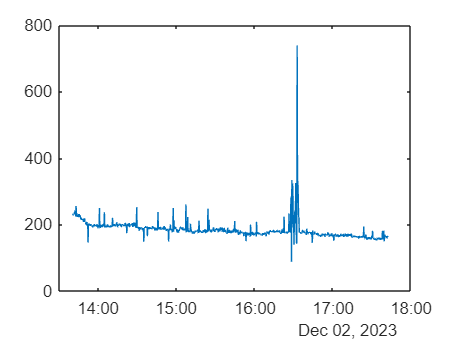


% Plot Data
plot(timestamps_2,data_2)


% Remove outlier using mean
A_1 = timetable(timestamps_2,data_2);
data_new_1 = filloutliers(A_1,'linear')

data_new_1 = 892×1 timetable
        timestamps_2        data_2
    ____________________    ______

    02-Dec-2023 13:40:39    226.51
    02-Dec-2023 13:40:55    226.25
    02-Dec-2023 13:41:11       226
    02-Dec-2023 13:41:27    225.74
    02-Dec-2023 13:41:44    225.47
    02-Dec-2023 13:42:00    225.21
    02-Dec-2023 13:42:16    224.95
    02-Dec-2023 13:42:33    224.68
    02-Dec-2023 13:42:49    224.42
    02-Dec-2023 13:43:06    224.15
    02-Dec-2023 13:43:22    223.89
    02-Dec-2023 13:43:38    223.63
    02-Dec-2023 13:43:54    223.38
    02-Dec-2023 13:44:11    222.84
    02-Dec-2023 13:44:27    222.33
    02-Dec-2023 13:44:43    222.33


for i = 1:height(data_new_1)
    data_new_1.Pump(i) = 100;
    data_new_1.Jumlah_adsorben(i)= 4;
end
data_new_1

data_new_1 = 892×3 timetable
        timestamps_2        data_2    Pump    Jumlah_adsorben
    ____________________    ______    ____    _______________

    02-Dec-2023 13:40:39    226.51    100            4       
    02-Dec-2023 13:40:55    226.25    100            4       
    02-Dec-2023 13:41:11       226    100            4       
    02-Dec-2023 13:41:27    225.74    100            4       
    02-Dec-2023 13:41:44    225.47    100            4       
    02-Dec-2023 13:42:00    225.21    100            4       
    02-Dec-2023 13:42:16    224.95    100            4       
    02-Dec-2023 13:42:33    224.68    100            4       
    02-Dec-2023 13:42:49    224.42    100            4       

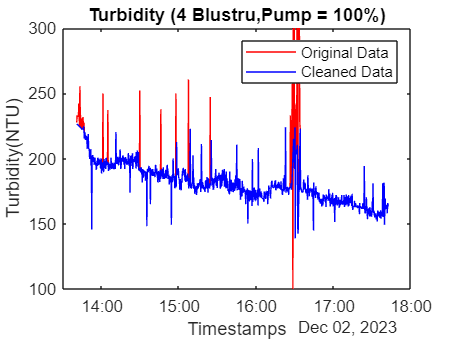


% visualize new_data
plot(timestamps_2,data_2,"r-")
hold on
plot(data_new_1.timestamps_2,data_new_1.data_2,"b-")
legend("Original Data","Cleaned Data")
title('Turbidity (4 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
ylim([100 300])
hold off

[data_3,timestamps_3,channelInfo_2] = thingSpeakRead(2328684,Fields=3,ReadKey='0FU0HYKO14RY4VAM',...
    DateRange=[datetime(2024,02,01,17,07,53),datetime(2024,02,01,20,41,15)])

data_3 =   231.4122
  228.7434
  231.4122
  230.0758
  228.7434
  222.1401
  224.7697
  230.0758
  242.2449
  228.7434


timestamps_3 = 790×1 datetime array
   01-Feb-2024 17:07:53
   01-Feb-2024 17:08:08
   01-Feb-2024 17:08:23
   01-Feb-2024 17:08:39
   01-Feb-2024 17:08:57
   01-Feb-2024 17:09:26
   01-Feb-2024 17:09:42
   01-Feb-2024 17:10:00
   01-Feb-2024 17:10:30
   01-Feb-2024 17:11:00
   01-Feb-2024 17:11:29
   01-Feb-2024 17:11:45
   01-Feb-2024 17:12:03
   01-Feb-2024 17:12:32
   01-Feb-2024 17:12:47
   01-Feb-2024 17:13:03
   01-Feb-2024 17:13:18
   01-Feb-2024 17:13:34
   01-Feb-2024 17:13:49
   01-Feb-2024 17:14:04
   01-Feb-2024 17:14:20
   01-Feb-2024 17:14:36
   01-Feb-2024 17:15:07
   01-Feb-2024 17:15:22
   01-Feb-2024 17:15:38
   01-Feb-2024 17:15:53
   01-Feb-2024 17:16:09
   01-Feb-2024 17:16:24
   01-Feb-2024 17:16:40
   01-Feb-2024 17:16:55


channelInfo_2 = struct with fields:
            ChannelID: 2328684
                 Name: 'Tugas Akhir Adsorbsi'
          Description: 'Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik'
             Latitude: 0
            Longitude: 0
             Altitude: []
              Created: 02-Nov-2023 13:39:14
              Updated: 31-Jan-2024 08:35:15
          LastEntryID: 2718
    FieldDescriptions: {'Turbidity_1'  'Turbidity_2'  'Turbidity_3'  'Turbidity_4'}
             FieldIDs: [1 2 3 4]
                  URL: 'https://api.thingspeak.com/channels/2328684/field/3.json?'


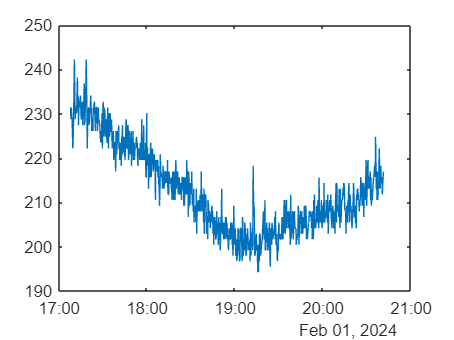


% Plot Data
plot(timestamps_3,data_3)


% Remove outlier using mean
A_2 = timetable(timestamps_3,data_3);
data_new_2 = filloutliers(A_2,'linear')

data_new_2 = 790×1 timetable
        timestamps_3        data_3
    ____________________    ______

    01-Feb-2024 17:07:53    231.41
    01-Feb-2024 17:08:08    228.74
    01-Feb-2024 17:08:23    231.41
    01-Feb-2024 17:08:39    230.08
    01-Feb-2024 17:08:57    228.74
    01-Feb-2024 17:09:26    222.14
    01-Feb-2024 17:09:42    224.77
    01-Feb-2024 17:10:00    230.08
    01-Feb-2024 17:10:30    229.41
    01-Feb-2024 17:11:00    228.74
    01-Feb-2024 17:11:29    231.41
    01-Feb-2024 17:11:45    231.41
    01-Feb-2024 17:12:03    230.08
    01-Feb-2024 17:12:32    238.15
    01-Feb-2024 17:12:47    231.41
    01-Feb-2024 17:13:03     234.1


for i = 1:height(data_new_2)
    data_new_2.Pump(i) = 100;
    data_new_2.Jumlah_adsorben(i)= 6;
end
data_new_2

data_new_2 = 790×3 timetable
        timestamps_3        data_3    Pump    Jumlah_adsorben
    ____________________    ______    ____    _______________

    01-Feb-2024 17:07:53    231.41    100            6       
    01-Feb-2024 17:08:08    228.74    100            6       
    01-Feb-2024 17:08:23    231.41    100            6       
    01-Feb-2024 17:08:39    230.08    100            6       
    01-Feb-2024 17:08:57    228.74    100            6       
    01-Feb-2024 17:09:26    222.14    100            6       
    01-Feb-2024 17:09:42    224.77    100            6       
    01-Feb-2024 17:10:00    230.08    100            6       
    01-Feb-2024 17:10:30    229.41    100            6       

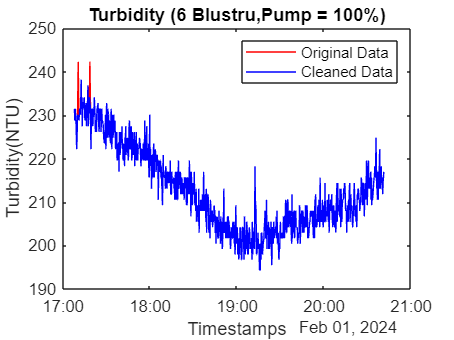


% visualize new_data
plot(timestamps_3,data_3,"r-")
hold on
plot(data_new_2.timestamps_3,data_new_2.data_3,"b-")
legend("Original Data","Cleaned Data")
title('Turbidity (6 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

filename = 'Preprocessing_Data_Adsorbsi.xlsx';
% writetimetable(data_new,filename,'Sheet',1)
% writetimetable(data_new_1,filename,'Sheet',2)
% writetimetable(A_2,filename,'Sheet',3)

Channel ID: **2415656**

Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik (Percobaan kedua)

#### Percobaan 1 -  Jumlah blustru : 4 buah

[data1,timestamps1,channelInfo1] = thingSpeakRead(2415656,Fields=1,ReadKey='UAISS2WW5C8Z616I', ...
    DateRange=[datetime(2024,02,05,12,02,30),datetime(2024,02,05,15,02,13)])

data1 =   256.1398
  207.9594
  215.6353
  184.5862
  185.7810
  185.7810
  191.8137
  201.6709
  206.6938
  238.1531


timestamps1 = 688×1 datetime array
   05-Feb-2024 12:02:40
   05-Feb-2024 12:02:56
   05-Feb-2024 12:03:11
   05-Feb-2024 12:03:27
   05-Feb-2024 12:03:42
   05-Feb-2024 12:03:58
   05-Feb-2024 12:04:13
   05-Feb-2024 12:04:29
   05-Feb-2024 12:04:45
   05-Feb-2024 12:05:00
   05-Feb-2024 12:05:15
   05-Feb-2024 12:05:31
   05-Feb-2024 12:05:46
   05-Feb-2024 12:06:02
   05-Feb-2024 12:06:17
   05-Feb-2024 12:06:33
   05-Feb-2024 12:06:48
   05-Feb-2024 12:07:04
   05-Feb-2024 12:07:19
   05-Feb-2024 12:07:35
   05-Feb-2024 12:07:50
   05-Feb-2024 12:08:06
   05-Feb-2024 12:08:21
   05-Feb-2024 12:08:37
   05-Feb-2024 12:08:52
   05-Feb-2024 12:09:08
   05-Feb-2024 12:09:23
   05-Feb-2024 12:09:39
   05-Feb-2024 12:09:54
   05-Feb-2024 12:10:10


channelInfo1 = struct with fields:
            ChannelID: 2415656
                 Name: 'Tugas Akhir Adsorbsi - 1'
          Description: 'Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik'
             Latitude: 0
            Longitude: 0
             Altitude: []
              Created: 30-Jan-2024 12:57:45
              Updated: 06-Feb-2024 12:38:20
          LastEntryID: 2273
    FieldDescriptions: {'Turbidity1_4'  'Turbidity2_4'  'Turbidity1_8'  'Turbidity2_8'  'Turbidity1_12'  'Turbidity2_12'}
             FieldIDs: [1 2 3 4 5 6]
                  URL: 'https://api.thingspeak.com/channels/2415656/field/1.json?'


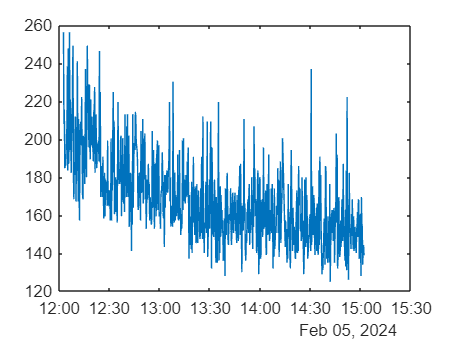

% Plot Data
figure(1)
plot(timestamps1,data1)


% Remove outlier using mean
A1 = timetable(timestamps1,data1);
data_new = filloutliers(A1,'nearest','mean')

data_new = 688×1 timetable
        timestamps1         data1 
    ____________________    ______

    05-Feb-2024 12:02:40    207.96
    05-Feb-2024 12:02:56    207.96
    05-Feb-2024 12:03:11    215.64
    05-Feb-2024 12:03:27    184.59
    05-Feb-2024 12:03:42    185.78
    05-Feb-2024 12:03:58    185.78
    05-Feb-2024 12:04:13    191.81
    05-Feb-2024 12:04:29    201.67
    05-Feb-2024 12:04:45    206.69
    05-Feb-2024 12:05:00    238.15
    05-Feb-2024 12:05:15     183.4
    05-Feb-2024 12:05:31    186.98
    05-Feb-2024 12:05:46    186.98
    05-Feb-2024 12:06:02    197.95
    05-Feb-2024 12:06:17    197.95
    05-Feb-2024 12:06:33    194.25


for i = 1:height(data_new)
    data_new.Pump(i) = 100;
    data_new.Jumlah_adsorben(i)= 4;
end
data_new

data_new = 688×3 timetable
        timestamps1         data1     Pump    Jumlah_adsorben
    ____________________    ______    ____    _______________

    05-Feb-2024 12:02:40    207.96    100            4       
    05-Feb-2024 12:02:56    207.96    100            4       
    05-Feb-2024 12:03:11    215.64    100            4       
    05-Feb-2024 12:03:27    184.59    100            4       
    05-Feb-2024 12:03:42    185.78    100            4       
    05-Feb-2024 12:03:58    185.78    100            4       
    05-Feb-2024 12:04:13    191.81    100            4       
    05-Feb-2024 12:04:29    201.67    100            4       
    05-Feb-2024 12:04:45    206.69    100            4       
 

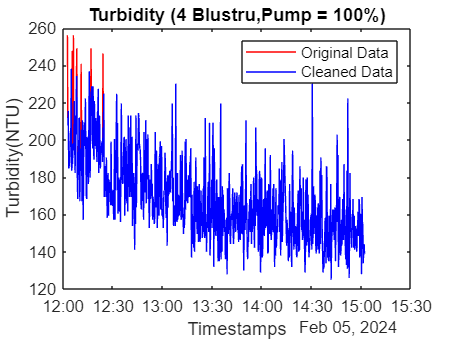


% visualize new_data
figure(2)
plot(timestamps1,data1,"r-")
hold on
plot(data_new.timestamps1,data_new.data1,"b-")
legend("Original Data","Cleaned Data")
title('Turbidity (4 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

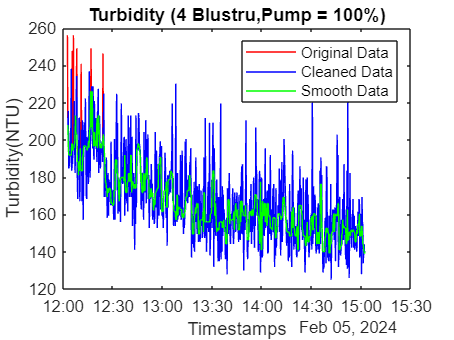

smooth_data1 = smoothdata(data_new,"movmedian","omitnan","SmoothingFactor",0.8);
% visualize new_data
figure(3)
plot(timestamps1,data1,"r-")
hold on
plot(data_new.timestamps1,data_new.data1,"b-")
hold on
plot(data_new.timestamps1,smooth_data1.data1,"g-")
legend("Original Data","Cleaned Data","Smooth Data")
title('Turbidity (4 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

data_new.SmoothData = smooth_data1.data1;
data_new

data_new = 688×4 timetable
        timestamps1         data1     Pump    Jumlah_adsorben    SmoothData
    ____________________    ______    ____    _______________    __________

    05-Feb-2024 12:02:40    207.96    100            4             207.96  
    05-Feb-2024 12:02:56    207.96    100            4             207.96  
    05-Feb-2024 12:03:11    215.64    100            4             196.87  
    05-Feb-2024 12:03:27    184.59    100            4             191.81  
    05-Feb-2024 12:03:42    185.78    100            4             191.81  
    05-Feb-2024 12:03:58    185.78    100            4             191.81  
    05-Feb-2024 12:04:13    191.81    100            4             191.81  

#### Percobaan 2 -  Jumlah blustru : 8 buah

[data2,timestamps2,channelInfo2] = thingSpeakRead(2415656,Fields=3,ReadKey='UAISS2WW5C8Z616I', ...
    DateRange=[datetime(2024,02,06,09,37,32),datetime(2024,02,06,12,30,20)])

data2 =   145.2481
  249.1431
  181.0256
  202.9206
  188.1824
  172.8550
  159.2969
  167.1370
  172.8550
  168.2727


timestamps2 = 661×1 datetime array
   06-Feb-2024 09:37:46
   06-Feb-2024 09:38:02
   06-Feb-2024 09:38:17
   06-Feb-2024 09:38:33
   06-Feb-2024 09:38:48
   06-Feb-2024 09:39:04
   06-Feb-2024 09:39:19
   06-Feb-2024 09:39:35
   06-Feb-2024 09:39:50
   06-Feb-2024 09:40:06
   06-Feb-2024 09:40:21
   06-Feb-2024 09:40:36
   06-Feb-2024 09:40:52
   06-Feb-2024 09:41:08
   06-Feb-2024 09:41:23
   06-Feb-2024 09:41:39
   06-Feb-2024 09:41:54
   06-Feb-2024 09:42:10
   06-Feb-2024 09:42:25
   06-Feb-2024 09:42:41
   06-Feb-2024 09:42:56
   06-Feb-2024 09:43:12
   06-Feb-2024 09:43:27
   06-Feb-2024 09:43:43
   06-Feb-2024 09:43:58
   06-Feb-2024 09:44:14
   06-Feb-2024 09:44:29
   06-Feb-2024 09:44:45
   06-Feb-2024 09:45:00
   06-Feb-2024 09:45:16


channelInfo2 = struct with fields:
            ChannelID: 2415656
                 Name: 'Tugas Akhir Adsorbsi - 1'
          Description: 'Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik'
             Latitude: 0
            Longitude: 0
             Altitude: []
              Created: 30-Jan-2024 12:57:45
              Updated: 06-Feb-2024 12:38:20
          LastEntryID: 2273
    FieldDescriptions: {'Turbidity1_4'  'Turbidity2_4'  'Turbidity1_8'  'Turbidity2_8'  'Turbidity1_12'  'Turbidity2_12'}
             FieldIDs: [1 2 3 4 5 6]
                  URL: 'https://api.thingspeak.com/channels/2415656/field/3.json?'


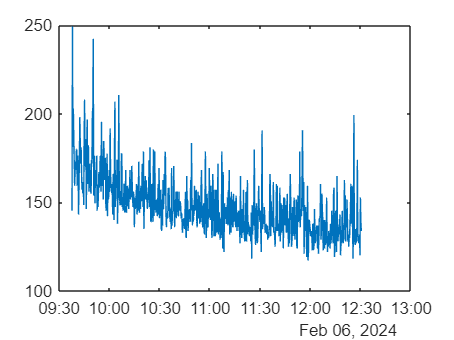

% Plot Data
figure(4)
plot(timestamps2,data2)


% Remove outlier using mean
A2 = timetable(timestamps2,data2);
data_new2 = filloutliers(A2,'nearest','mean')

data_new2 = 661×1 timetable
        timestamps2         data2 
    ____________________    ______

    06-Feb-2024 09:37:46    145.25
    06-Feb-2024 09:38:02    181.03
    06-Feb-2024 09:38:17    181.03
    06-Feb-2024 09:38:33    188.18
    06-Feb-2024 09:38:48    188.18
    06-Feb-2024 09:39:04    172.85
    06-Feb-2024 09:39:19     159.3
    06-Feb-2024 09:39:35    167.14
    06-Feb-2024 09:39:50    172.85
    06-Feb-2024 09:40:06    168.27
    06-Feb-2024 09:40:21    179.85
    06-Feb-2024 09:40:36    179.85
    06-Feb-2024 09:40:52     159.3
    06-Feb-2024 09:41:08    176.33
    06-Feb-2024 09:41:23    172.85
    06-Feb-2024 09:41:39    143.15


for i = 1:height(data_new2)
    data_new2.Pump(i) = 100;
    data_new2.Jumlah_adsorben(i)= 12;
end
data_new2

data_new2 = 661×3 timetable
        timestamps2         data2     Pump    Jumlah_adsorben
    ____________________    ______    ____    _______________

    06-Feb-2024 09:37:46    145.25    100            8       
    06-Feb-2024 09:38:02    181.03    100            8       
    06-Feb-2024 09:38:17    181.03    100            8       
    06-Feb-2024 09:38:33    188.18    100            8       
    06-Feb-2024 09:38:48    188.18    100            8       
    06-Feb-2024 09:39:04    172.85    100            8       
    06-Feb-2024 09:39:19     159.3    100            8       
    06-Feb-2024 09:39:35    167.14    100            8       
    06-Feb-2024 09:39:50    172.85    100            8       


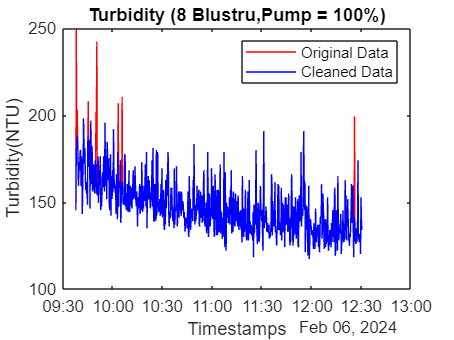


% visualize new_data
figure(5)
plot(timestamps2,data2,"r-")
hold on
plot(data_new2.timestamps2,data_new2.data2,"b-")
legend("Original Data","Cleaned Data")
title('Turbidity (8 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

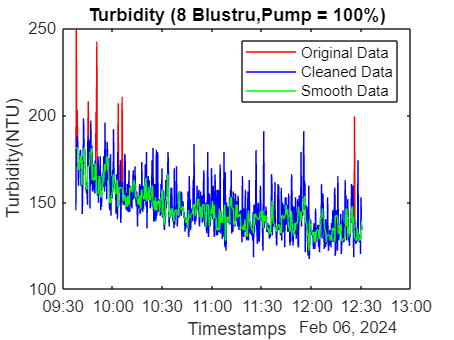

smooth_data2 = smoothdata(data_new2,"movmedian","omitnan","SmoothingFactor",0.8);
% visualize new_data
figure(6)
plot(timestamps2,data2,"r-")
hold on
plot(data_new2.timestamps2,data_new2.data2,"b-")
hold on
plot(data_new2.timestamps2,smooth_data2.data2,"g-")
legend("Original Data","Cleaned Data","Smooth Data")
title('Turbidity (8 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

data_new2.SmoothData = smooth_data2.data2;
data_new2

data_new2 = 661×4 timetable
        timestamps2         data2     Pump    Jumlah_adsorben    SmoothData
    ____________________    ______    ____    _______________    __________

    06-Feb-2024 09:37:46    145.25    100            8             181.03  
    06-Feb-2024 09:38:02    181.03    100            8             181.03  
    06-Feb-2024 09:38:17    181.03    100            8             181.03  
    06-Feb-2024 09:38:33    188.18    100            8             181.03  
    06-Feb-2024 09:38:48    188.18    100            8             181.03  
    06-Feb-2024 09:39:04    172.85    100            8             172.85  
    06-Feb-2024 09:39:19     159.3    100            8             172.85 

#### Percobaan 3 -  Jumlah blustru : 12 buah

[data3,timestamps3,channelInfo3] = thingSpeakRead(2415656,Fields=5,ReadKey='UAISS2WW5C8Z616I', ...
    DateRange=[datetime(2024,02,06,13,06,09),datetime(2024,02,06,16,14,19)])

data3 =   228.7434
  232.7526
  206.6938
  205.4321
  199.1830
  196.7109
  218.2253
  201.6709
  210.5023
  214.3462


timestamps3 = 717×1 datetime array
   06-Feb-2024 13:06:09
   06-Feb-2024 13:06:24
   06-Feb-2024 13:06:40
   06-Feb-2024 13:06:56
   06-Feb-2024 13:07:11
   06-Feb-2024 13:07:26
   06-Feb-2024 13:07:42
   06-Feb-2024 13:07:58
   06-Feb-2024 13:08:13
   06-Feb-2024 13:08:29
   06-Feb-2024 13:08:44
   06-Feb-2024 13:08:59
   06-Feb-2024 13:09:15
   06-Feb-2024 13:09:30
   06-Feb-2024 13:09:46
   06-Feb-2024 13:10:01
   06-Feb-2024 13:10:17
   06-Feb-2024 13:10:32
   06-Feb-2024 13:10:48
   06-Feb-2024 13:11:04
   06-Feb-2024 13:11:19
   06-Feb-2024 13:11:34
   06-Feb-2024 13:11:50
   06-Feb-2024 13:12:06
   06-Feb-2024 13:12:21
   06-Feb-2024 13:12:36
   06-Feb-2024 13:12:52
   06-Feb-2024 13:13:08
   06-Feb-2024 13:13:23
   06-Feb-2024 13:13:38


channelInfo3 = struct with fields:
            ChannelID: 2415656
                 Name: 'Tugas Akhir Adsorbsi - 1'
          Description: 'Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik'
             Latitude: 0
            Longitude: 0
             Altitude: []
              Created: 30-Jan-2024 12:57:45
              Updated: 06-Feb-2024 12:38:20
          LastEntryID: 2273
    FieldDescriptions: {'Turbidity1_4'  'Turbidity2_4'  'Turbidity1_8'  'Turbidity2_8'  'Turbidity1_12'  'Turbidity2_12'}
             FieldIDs: [1 2 3 4 5 6]
                  URL: 'https://api.thingspeak.com/channels/2415656/field/5.json?'


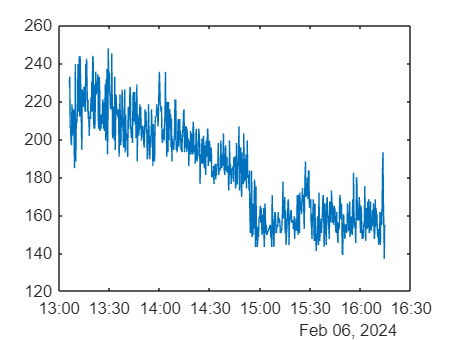

% Plot Data
figure(7)
plot(timestamps3,data3)


% Remove outlier using mean
A3 = timetable(timestamps3,data3);
data_new3 = filloutliers(A3,'nearest','mean')

data_new3 = 717×1 timetable
        timestamps3         data3 
    ____________________    ______

    06-Feb-2024 13:06:09    228.74
    06-Feb-2024 13:06:24    232.75
    06-Feb-2024 13:06:40    206.69
    06-Feb-2024 13:06:56    205.43
    06-Feb-2024 13:07:11    199.18
    06-Feb-2024 13:07:26    196.71
    06-Feb-2024 13:07:42    218.23
    06-Feb-2024 13:07:58    201.67
    06-Feb-2024 13:08:13     210.5
    06-Feb-2024 13:08:29    214.35
    06-Feb-2024 13:08:44    215.64
    06-Feb-2024 13:08:59    201.67
    06-Feb-2024 13:09:15    184.59
    06-Feb-2024 13:09:30    200.42
    06-Feb-2024 13:09:46    239.51
    06-Feb-2024 13:10:01    188.18


for i = 1:height(data_new3)
    data_new3.Pump(i) = 100;
    data_new3.Jumlah_adsorben(i)= 8;
end
data_new3

data_new3 = 717×3 timetable
        timestamps3         data3     Pump    Jumlah_adsorben
    ____________________    ______    ____    _______________

    06-Feb-2024 13:06:09    228.74    100            8       
    06-Feb-2024 13:06:24    232.75    100            8       
    06-Feb-2024 13:06:40    206.69    100            8       
    06-Feb-2024 13:06:56    205.43    100            8       
    06-Feb-2024 13:07:11    199.18    100            8       
    06-Feb-2024 13:07:26    196.71    100            8       
    06-Feb-2024 13:07:42    218.23    100            8       
    06-Feb-2024 13:07:58    201.67    100            8       
    06-Feb-2024 13:08:13     210.5    100            8       


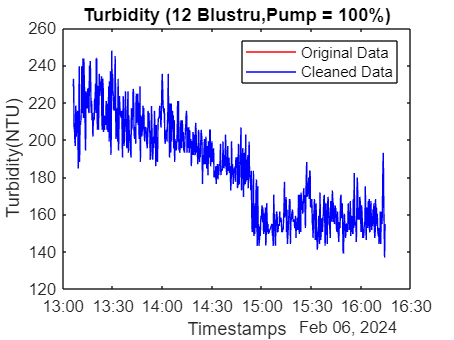


% visualize new_data
figure(8)
plot(timestamps3,data3,"r-")
hold on
plot(data_new3.timestamps3,data_new3.data3,"b-")
legend("Original Data","Cleaned Data")
title('Turbidity (12 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

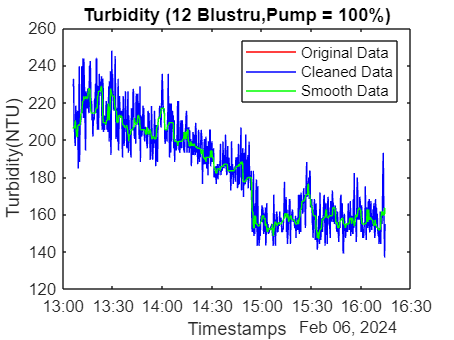

smooth_data3 = smoothdata(data_new3,"movmedian","omitnan","SmoothingFactor",0.7);
% visualize new_data
figure(9)
plot(timestamps3,data3,"r-")
hold on
plot(data_new3.timestamps3,data_new3.data3,"b-")
hold on
plot(data_new3.timestamps3,smooth_data3.data3,"g-")
legend("Original Data","Cleaned Data","Smooth Data")
title('Turbidity (12 Blustru,Pump = 100%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

data_new3.SmoothData = smooth_data3.data3;
data_new3

data_new3 = 717×4 timetable
        timestamps3         data3     Pump    Jumlah_adsorben    SmoothData
    ____________________    ______    ____    _______________    __________

    06-Feb-2024 13:06:09    228.74    100            8             206.06  
    06-Feb-2024 13:06:24    232.75    100            8             206.69  
    06-Feb-2024 13:06:40    206.69    100            8             206.06  
    06-Feb-2024 13:06:56    205.43    100            8             206.69  
    06-Feb-2024 13:07:11    199.18    100            8              208.6  
    06-Feb-2024 13:07:26    196.71    100            8              210.5  
    06-Feb-2024 13:07:42    218.23    100            8             206.69 

Channel ID: **2424327**

Akuisisi Data Pengujian Plant Adsorpsi Lab Pemrosesan Material untuk Sistem Pengolahan Limbah Batik

#### Percobaan 1 -  Jumlah blustru : 4 buah

[data_50_1,timestamps_50_1,channelInfo_50_1] = thingSpeakRead(2424327,Fields=1,ReadKey='W3MHJI6HW55AMWT9', ...
    DateRange=[datetime(2024,02,07,09,54,41),datetime(2024,02,07,12,12,17)])

data_50_1 =   105.2952
  132.8701
  152.7302
  144.1950
  127.8799
  136.9332
  137.9587
  128.8700
  134.8938
  150.5728


timestamps_50_1 = 532×1 datetime array
   07-Feb-2024 09:54:41
   07-Feb-2024 09:54:57
   07-Feb-2024 09:55:12
   07-Feb-2024 09:55:28
   07-Feb-2024 09:55:43
   07-Feb-2024 09:55:59
   07-Feb-2024 09:56:14
   07-Feb-2024 09:56:30
   07-Feb-2024 09:56:45
   07-Feb-2024 09:57:01
   07-Feb-2024 09:57:17
   07-Feb-2024 09:57:32
   07-Feb-2024 09:57:47
   07-Feb-2024 09:58:03
   07-Feb-2024 09:58:18
   07-Feb-2024 09:58:34
   07-Feb-2024 09:58:49
   07-Feb-2024 09:59:05
   07-Feb-2024 09:59:20
   07-Feb-2024 09:59:36
   07-Feb-2024 09:59:51
   07-Feb-2024 10:00:07
   07-Feb-2024 10:00:22
   07-Feb-2024 10:00:38
   07-Feb-2024 10:00:53
   07-Feb-2024 10:01:09
   07-Feb-2024 10:01:24
   07-Feb-2024 10:01:40
   07-Feb-2024 10:01:55
   07-Feb-2024 10:02:11


channelInfo_50_1 = struct with fields:
            ChannelID: 2424327
                 Name: 'Tugas Akhir Adsorbsi - 50%'
          Description: ''
             Latitude: 0
            Longitude: 0
             Altitude: []
              Created: 07-Feb-2024 09:09:44
              Updated: 07-Feb-2024 09:09:44
          LastEntryID: 676
    FieldDescriptions: {'Turbidity_1'  'Turbidity_2'}
             FieldIDs: [1 2]
                  URL: 'https://api.thingspeak.com/channels/2424327/field/1.json?'


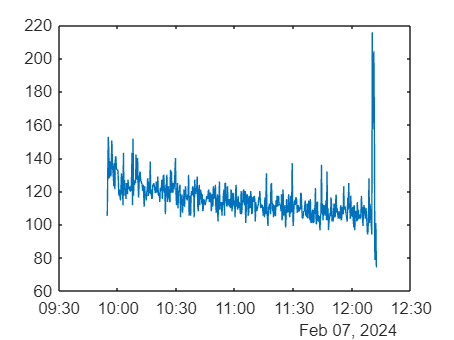

% Plot Data
figure(10)
plot(timestamps_50_1,data_50_1)


% Remove outlier using mean
A_50_1 = timetable(timestamps_50_1,data_50_1);
data_new_50 = filloutliers(A_50_1,'nearest','mean')

data_new_50 = 532×1 timetable
      timestamps_50_1       data_50_1
    ____________________    _________

    07-Feb-2024 09:54:41      105.3  
    07-Feb-2024 09:54:57     132.87  
    07-Feb-2024 09:55:12     132.87  
    07-Feb-2024 09:55:28     144.19  
    07-Feb-2024 09:55:43     127.88  
    07-Feb-2024 09:55:59     136.93  
    07-Feb-2024 09:56:14     137.96  
    07-Feb-2024 09:56:30     128.87  
    07-Feb-2024 09:56:45     134.89  
    07-Feb-2024 09:57:01     150.57  
    07-Feb-2024 09:57:17     137.96  
    07-Feb-2024 09:57:32     132.87  
    07-Feb-2024 09:57:47     128.87  
    07-Feb-2024 09:58:03     122.99  
    07-Feb-2024 09:58:18     136.93  


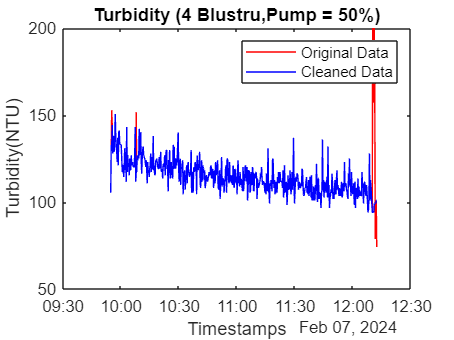

for i = 1:height(data_new_50)
    data_new_50.Pump(i) = 50;
    data_new_50.Jumlah_adsorben(i)= 4;
end

% visualize new_data
figure(11)
plot(timestamps_50_1,data_50_1,"r-")
hold on
plot(data_new_50.timestamps_50_1,data_new_50.data_50_1,"b-")
legend("Original Data","Cleaned Data")
title('Turbidity (4 Blustru,Pump = 50%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
ylim([50 200])
hold off

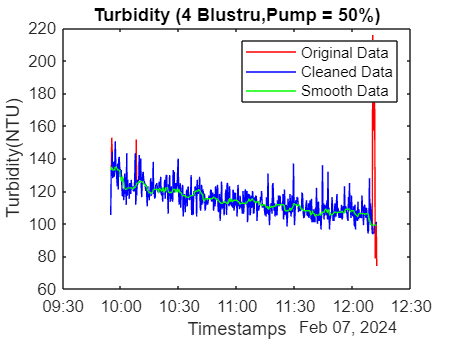

smooth_data_50_1 = smoothdata(data_new_50,"movmedian","omitnan","SmoothingFactor",0.8);
% visualize new_data
figure(12)
plot(timestamps_50_1,data_50_1,"r-")
hold on
plot(data_new_50.timestamps_50_1,data_new_50.data_50_1,"b-")
hold on
plot(data_new_50.timestamps_50_1,smooth_data_50_1.data_50_1,"g-")
legend("Original Data","Cleaned Data","Smooth Data")
title('Turbidity (4 Blustru,Pump = 50%)')
xlabel('Timestamps')
ylabel('Turbidity(NTU)')
hold off

data_new_50.SmoothData = smooth_data_50_1.data_50_1;
data_new_50

data_new_50 = 532×4 timetable
      timestamps_50_1       data_50_1    Pump    Jumlah_adsorben    SmoothData
    ____________________    _________    ____    _______________    __________

    07-Feb-2024 09:54:41      105.3       50            4             132.87  
    07-Feb-2024 09:54:57     132.87       50            4             133.88  
    07-Feb-2024 09:55:12     132.87       50            4             134.89  
    07-Feb-2024 09:55:28     144.19       50            4             133.88  
    07-Feb-2024 09:55:43     127.88       50            4             132.87  
    07-Feb-2024 09:55:59     136.93       50            4             132.87  
    07-Feb-2024 09:56:14     137.96       50    

filename = 'SmoothData_Processing.xlsx';
writetimetable(data_new,filename,'Sheet','4 Adsorben -100')
writetimetable(data_new2,filename,'Sheet','8 Adsorben -100')
writetimetable(data_new3,filename,'Sheet','12 Adsorben -100')
writetimetable(data_new_50,filename,'Sheet','4 Adsorben -50')